# Derivative operators in polar coordinates

clear, clf

Get operators

N = 35;
M = 20;
[r, a, rr, aa, I, D1r, D2r, D3r, D4r, D2a, D4a, bc] = get_operators(N, M);

Differentiate function $\exp \left(-\frac{{\left(x-0\ldotp 3\right)}^2 -y^2 }{0\ldotp 1}\right)$

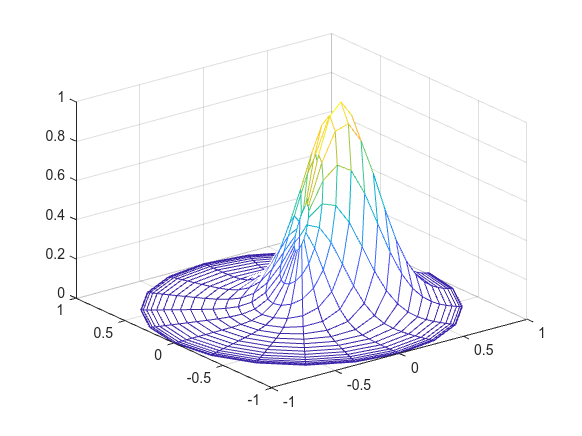

% visualise grid
f = @(x,y) exp(-((x-0.3).^2+y.^2)/0.1);
[xx, yy] = pol2cart(a, r);
zz = f(xx,yy);
mesh(xx, yy, zz)

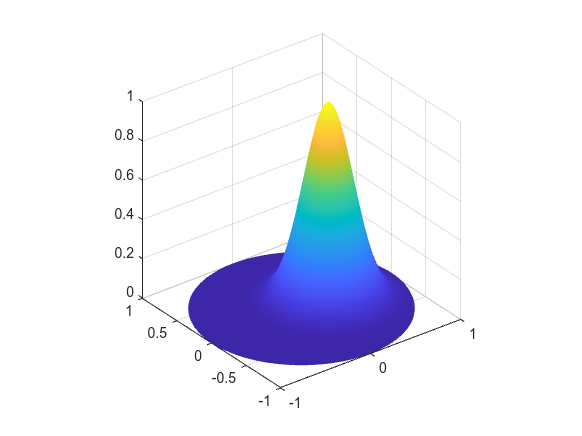

% plot with interpolation
zz = zz(:);
my_plot(r, a, zz)

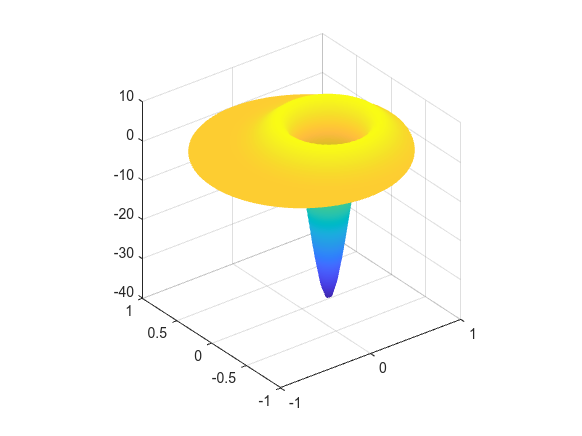

% laplacian
L = D2r + D1r./rr + D2a./rr.^2;
my_plot(r, a, L*zz)

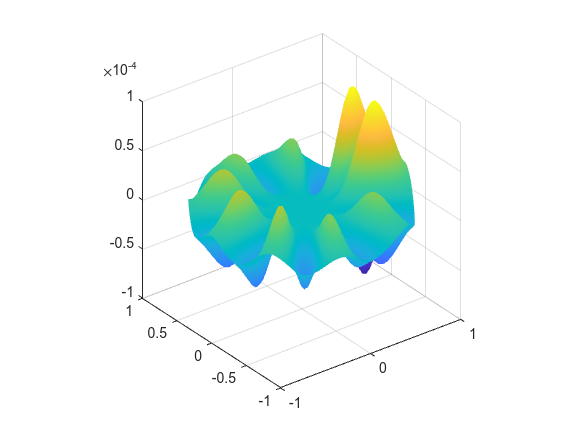

% error
Lf = @(x,y) (400*x.^2+400*y.^2-240*x-4).*f(x,y);
exact = Lf(xx, yy);
exact = exact(:);
my_plot(r, a, exact-L*zz)

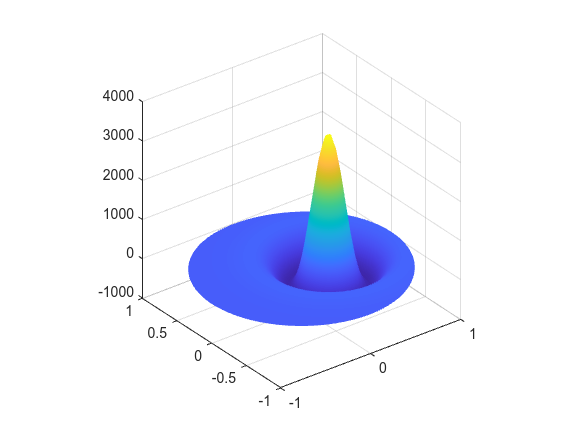

% biharmonic operator
biharm = D4r + 2*D2r*D2a./rr.^2 + D4a./rr.^4 + 2*D3r./rr - 2*D1r*D2a./rr.^3 - D2r./rr.^2 + 4*D2a./rr.^4 + D1r./rr.^3;
my_plot(r, a, biharm*zz)

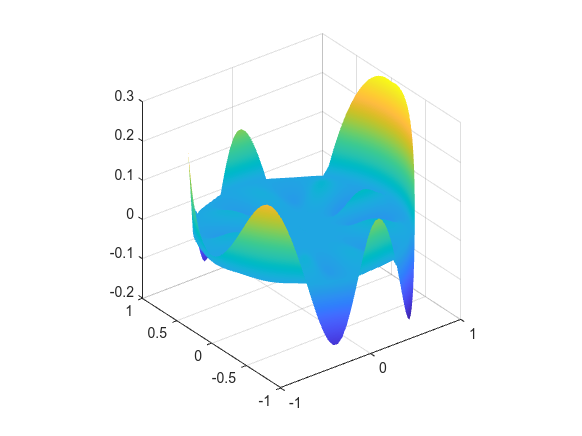

% error
LLf = @(x,y) (160000*x.^4-192000*x.^3+38400*x.^2+11520*x-1824+160000*y.^4-48000*y.^2+1200+640*(25*x.^2-15*x+1).*(20*y.^2-1)).*f(x,y);
exact = LLf(xx, yy);
exact = exact(:);
my_plot(r, a, exact-biharm*zz)

Azimuthal derivative

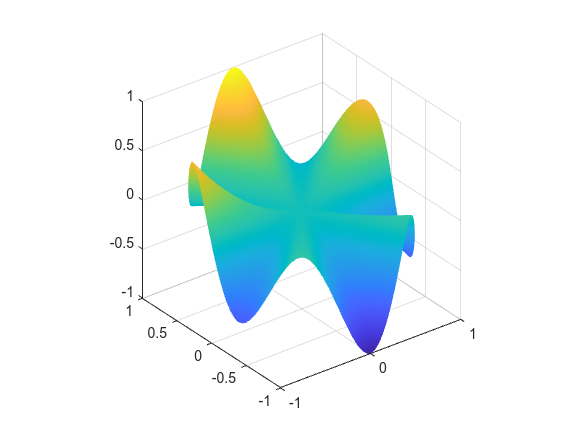

f = @(r,a) r.^2.*cos(2*a).*sin(3*a);
zz = f(rr,aa);
my_plot(r, a, zz)

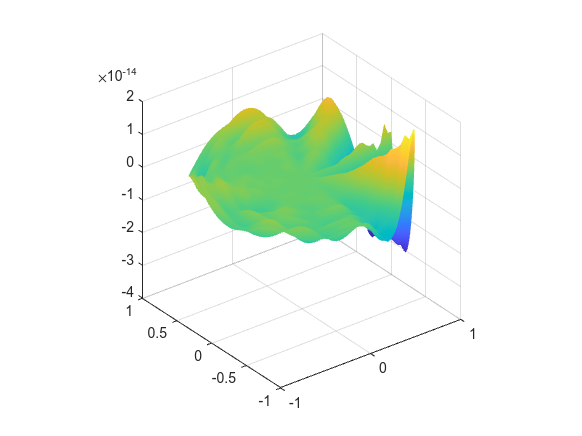

ddf = @(r,a) -r.^2.*(13*cos(2*a).*sin(3*a)+12*sin(2*a).*cos(3*a));
my_plot(r, a, D2a*zz-ddf(rr,aa))

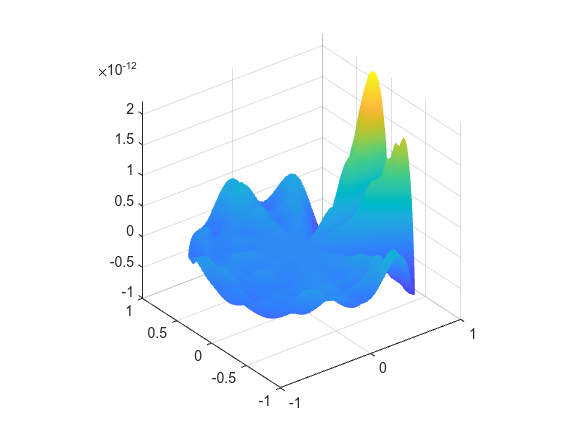

ddddf = @(r,a) r.^2.*(313*cos(2*a).*sin(3*a)+312*sin(2*a).*cos(3*a));
my_plot(r, a, D4a*zz-ddddf(rr,aa))

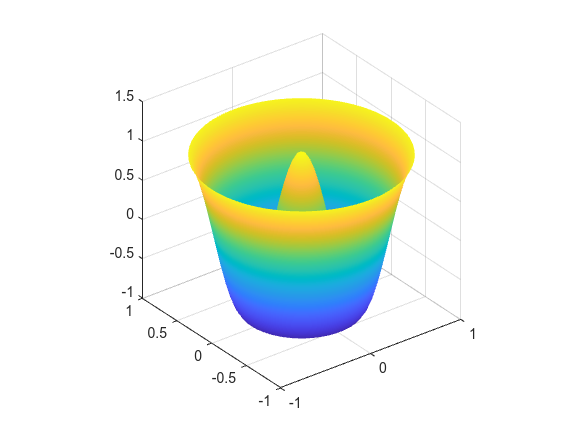

f = @(r) cos(6*r);
zz = f(rr);
my_plot(r, a, zz)

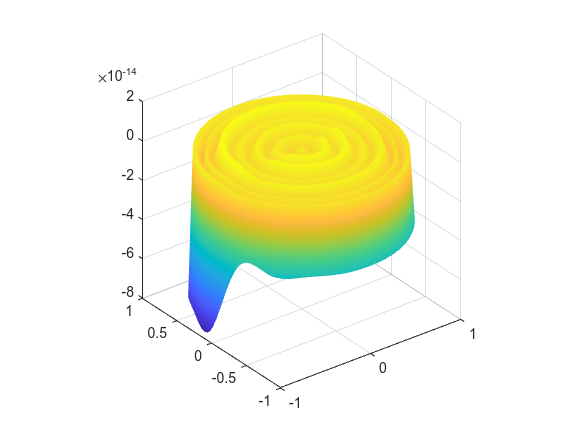

my_plot(r, a, -6*sin(6*rr)-D1r*zz)

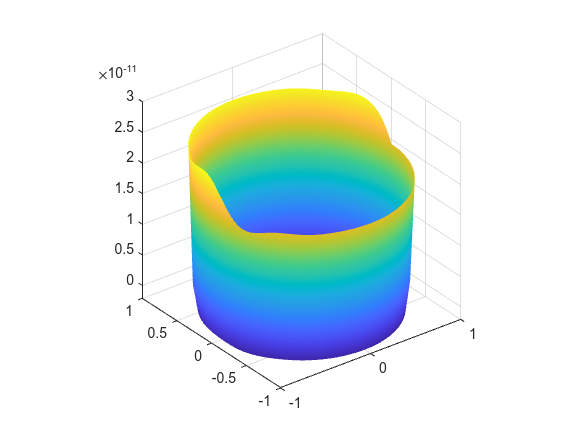

my_plot(r, a, -36*cos(6*rr)-D2r*zz)

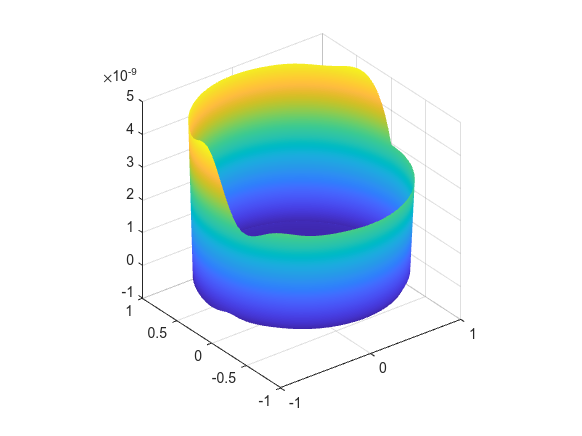

my_plot(r, a, 6^3*sin(6*rr)-D3r*zz)

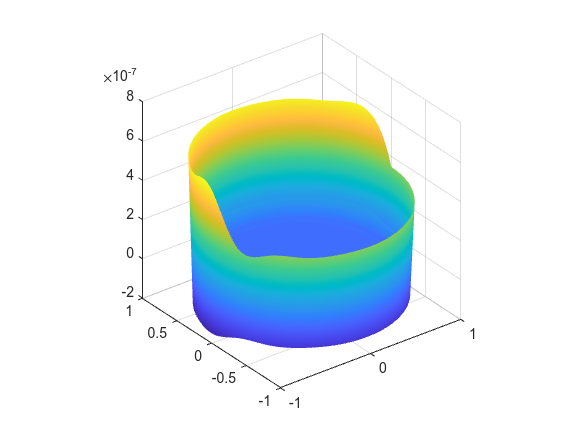

my_plot(r, a, 6^4*cos(6*rr)-D4r*zz)